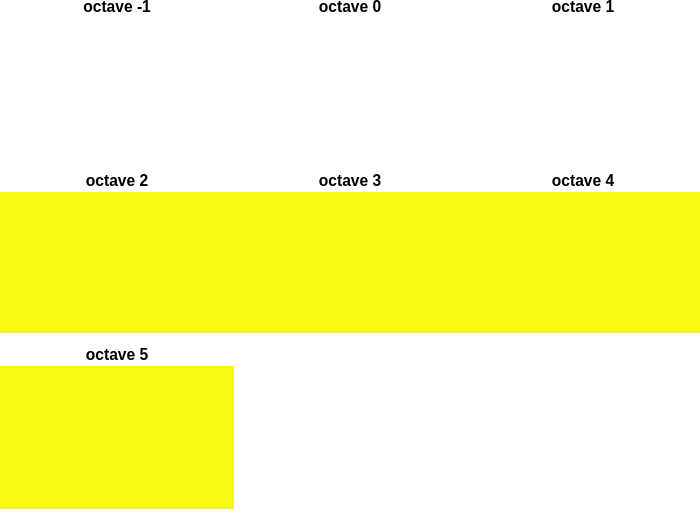

clear all; close all;

%VLFEATROOT = '/home/mlrosenquist/MATLAB Add-Ons/computer-vision-and-ml/vlfeat-0.9.21-bin/vlfeat-0.9.21';

%addpath('MatlabSourceFiles');
%run([VLFEATROOT,'/toolbox/vl_setup.m']);

% Load image
I = imread('RSA.jpg');

% Construct scale space (Gaussian pyramid)
[frames, descrp,info] = vl_covdet(single(I),'OctaveResolution',3);
gss = info.gss;
vl_plotss(gss);

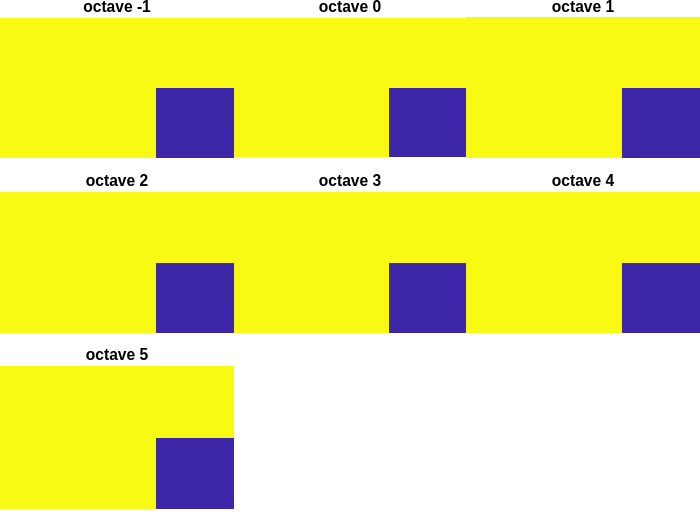


octaves = gss.lastOctave-gss.firstOctave+1;
gssSubdivs = gss.octaveLastSubdivision-gss.octaveFirstSubdivision+1;

% Show Difference of Gaussians (DoGs)
figure
DoGs = info.css;
vl_plotss(DoGs);

Why does Figure 2 only have 5 subdivision/suboctaves per octave (ignore the dark blue), whereas Figure 1 has 6?


% Find local extrema
DoGsSubdivs = DoGs.octaveLastSubdivision-DoGs.octaveFirstSubdivision+1;
Maxima = {};
Minima = {};
MaximaNonEdges = {};
MinimaNonEdges = {};
HarrisThreshold = 0.03;
for o=1:octaves
    [H,W,~] = size(DoGs.data{o});
    for s=2:DoGsSubdivs-1
        fprintf('Calculating local max/min of octave %d/%d, subdivision %d/%d\n',o,octaves,s-1,DoGsSubdivs-2)
        data = DoGs.data{o}(:,:,s-1:s+1);
        localMax = imregionalmax(data);
        localMax = localMax(:,:,2); % Remove lower and upper subdivisions
        localMin = imregionalmin(data);
        localMin = localMin(:,:,2); % Remove lower and upper subdivisions
        
        dataMid = data(:,:,2);
        % Discard local maxima less than 10% of the global maximum
        Ithr = max([0 0.15*max(dataMid(localMax))]);
        localMax(dataMid < Ithr) = 0;
        % Discard local minima larger than 20% of the global minimum
        Ithr = min([0 0.15*min(dataMid(localMin))]);
        localMin(dataMid > Ithr) = 0;
        
        Maxima{o,s-1} = localMax;
        Minima{o,s-1} = localMin;
        
        % Remove edge responses
        [Ix,Iy] = gradient(DoGs.data{o}(:,:,s));
        Ixx = imfilter(Ix.^2,fspecial('gaussian',3,0.5));
        Iyy = imfilter(Iy.^2,fspecial('gaussian',3,0.5));
        Ixy = imfilter(Ix.*Iy,fspecial('gaussian',3,0.5));
        
        % Exercise: modify localMax and localMin by removing blobs whose
        % Harris measures are below 'HarrisThreshold'
        
        % Hint: get a list all found blobs: find(localMax == 1)
        % Hint: remove blob with command: localMax(index) = 0
        
        indsMax = find(localMax == 1);
        indsMin = find(localMin == 1);
        % Combine indices to loop through both local maxima and minima in a
        % single loop. Could also be done in two separate loops.
        inds = [indsMax;indsMin];
        for i=1:length(inds)
            M = [ Ixx(inds(i)) Ixy(inds(i))
                Ixy(inds(i)) Iyy(inds(i)) ];
            d = eig(M);
            lambda_max=max(d);
            lambda_min=min(d);
            
            R = lambda_max*lambda_min/(lambda_max+lambda_min);
            
            if R<HarrisThreshold
                if ismember(inds(i),indsMax)
                    localMax(inds(i)) = 0;
                elseif ismember(inds(i),indsMin)
                    localMin(inds(i)) = 0;
                end
            end
        end
        
        % The modified localMax and localMin are stored for each scale
        MaximaNonEdges{o,s-1} = localMax;
        MinimaNonEdges{o,s-1} = localMin;
    end
end

Calculating local max/min of octave 1/7, subdivision 1/3
Calculating local max/min of octave 1/7, subdivision 2/3
Calculating local max/min of octave 1/7, subdivision 3/3
Calculating local max/min of octave 2/7, subdivision 1/3
Calculating local max/min of octave 2/7, subdivision 2/3
Calculating local max/min of octave 2/7, subdivision 3/3
Calculating local max/min of octave 3/7, subdivision 1/3
Calculating local max/min of octave 3/7, subdivision 2/3
Calculating local max/min of octave 3/7, subdivision 3/3
Calculating local max/min of octave 4/7, subdivision 1/3
Calculating local max/min of octave 4/7, subdivision 2/3
Calculating local max/min of octave 4/7, subdivision 3/3
Calculating local max/min of octave 5/7, subdivision 1/3
Calculating local max/min of octave 5/7, subdivision 2/3
Calculating local max/min of octave 5/7, subdivision 3/3
Calculating local max/min of octave 6/7, subdivision 1/3
Calculating local max/min of octave 6/7, subdivision 2/3
Calculating local max/min of oc

## Show a single scale

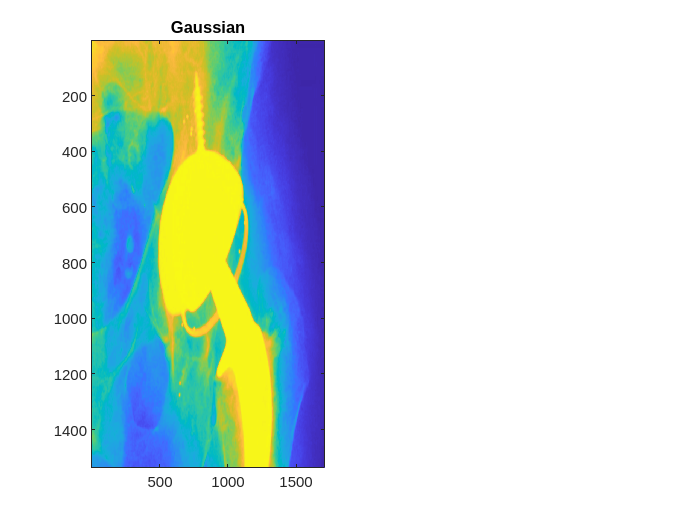

octave = 1;
suboctave = 3;
figure
subplot(121);imagesc(gss.data{octave}(:,:,suboctave));title('Gaussian');hold on;

    showBlobs(Maxima{octave,suboctave},'rx');

Unrecognized function or variable 'showBlobs'.

showBlobs(Minima{octave,suboctave},'bx');
subplot(122);imagesc(DoGs.data{octave}(:,:,suboctave));title('Difference of Gaussians');hold on;
showBlobs(Maxima{octave,suboctave},'rx');
showBlobs(Minima{octave,suboctave},'bx');

figure
subplot(121);imagesc(DoGs.data{octave}(:,:,suboctave));title('All blobs');hold on;
showBlobs(Maxima{octave,suboctave},'rx');
showBlobs(Minima{octave,suboctave},'bx');
subplot(122);imagesc(DoGs.data{octave}(:,:,suboctave));title('Edges removed');hold on;
showBlobs(MaximaNonEdges{octave,suboctave},'rx');
showBlobs(MinimaNonEdges{octave,suboctave},'bx');